# **2D and 3D Fitting**

[filepath,~,~] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(filepath);
addpath(fullfile(filepath,'myfunc'),'-begin')

**Functions:**

- **polyfit2**

- **PolyInterpSurf**

- **PolyInterpScatterZ**

- **polyfit3**

- **PolyInterpScatterMag**

- **bezierfit2:**

- **BezierInterpSurf**

- **BezierInterpScatterZ**

- **bezierfit3**

- **BezierInterpScatterMag**

**Polynomials vs. Bezier**

### Create Testing Data

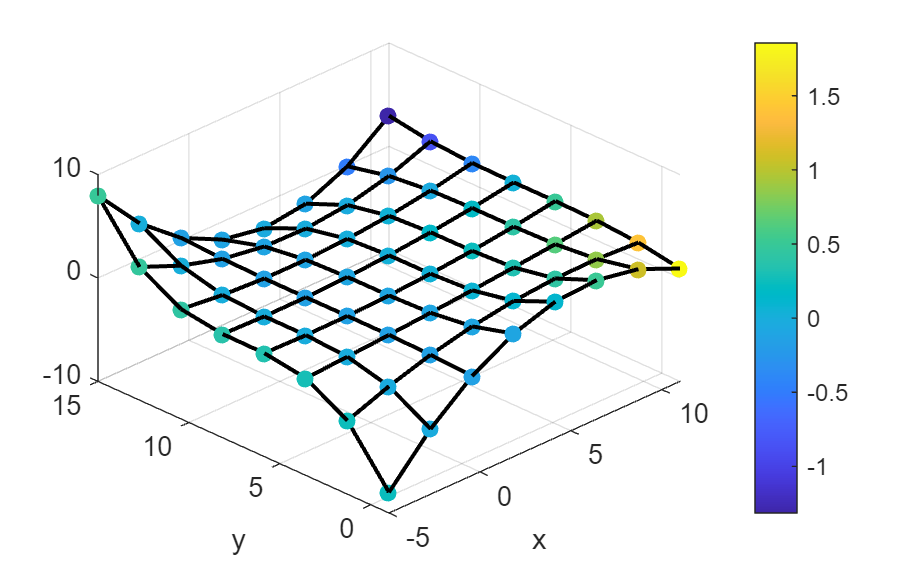

[xx0,yy0,zz0,mm0] = newdata(8);
[xs0,ys0,zs0,ms0] = ...
    deal(reshape(xx0,[],1),reshape(yy0,[],1),reshape(zz0,[],1),reshape(mm0,[],1));

f = figure;
surf(xx0,yy0,zz0,'FaceColor','none','LineWidth',1.5);hold on
scatter3(xs0,ys0,zs0,40,ms0,'filled');
view([-45 42]); xlabel('x'); ylabel('y');clim([min(ms0),max(ms0)]); colorbar
set(f,'Units','normalized','Position',[0,0,0.3,0.3])

# **polyfit2**

**Fit the 3rd Dimension Data**

order_pos = [3,3]; % Fitting Order

Return n*1 fitting coefficient, use GetPolyBasis Function to get the fitting formular.

c_fit_pos = polyfit2(xs0,ys0,zs0,order_pos);

fc = GetPolyBasis(2,order_pos)

fc = function_handle with value:
    @(ones,x,y)[ones,x,x.^2,x.^3,y,x.*y,x.^2.*y,x.^3.*y,y.^2,x.*y.^2,x.^2.*y.^2,x.^3.*y.^2,y.^3,x.*y.^3,x.^2.*y.^3,x.^3.*y.^3]


Return fitting coefficient in matrix form.

mx_fit_pos = polyfit2(xs0,ys0,zs0,order_pos,'matrix')

mx_fit_pos =     0.0779   -0.0312    0.0039   -0.0002
    0.7795   -0.3122    0.0446   -0.0021
   -0.0610    0.0312   -0.0045    0.0002
    0.0000   -0.0000    0.0000    0.0000


Matrix form is convenience to interpulate surface, also it contains fitting order information.

To convert matrix form to array form:

Size of matrix form coefficient: fitting_order_x * fitting_order_y

# **PolyInterpSurf**

**Interpolation Surface using x,y value**

x1 = linspace(-5,11,25)';
y1 = linspace(-1,15,25)';

[xx1,yy1,zz1] = PolyInterpSurf(x1,y1,mx_fit_pos);

Plot to Check

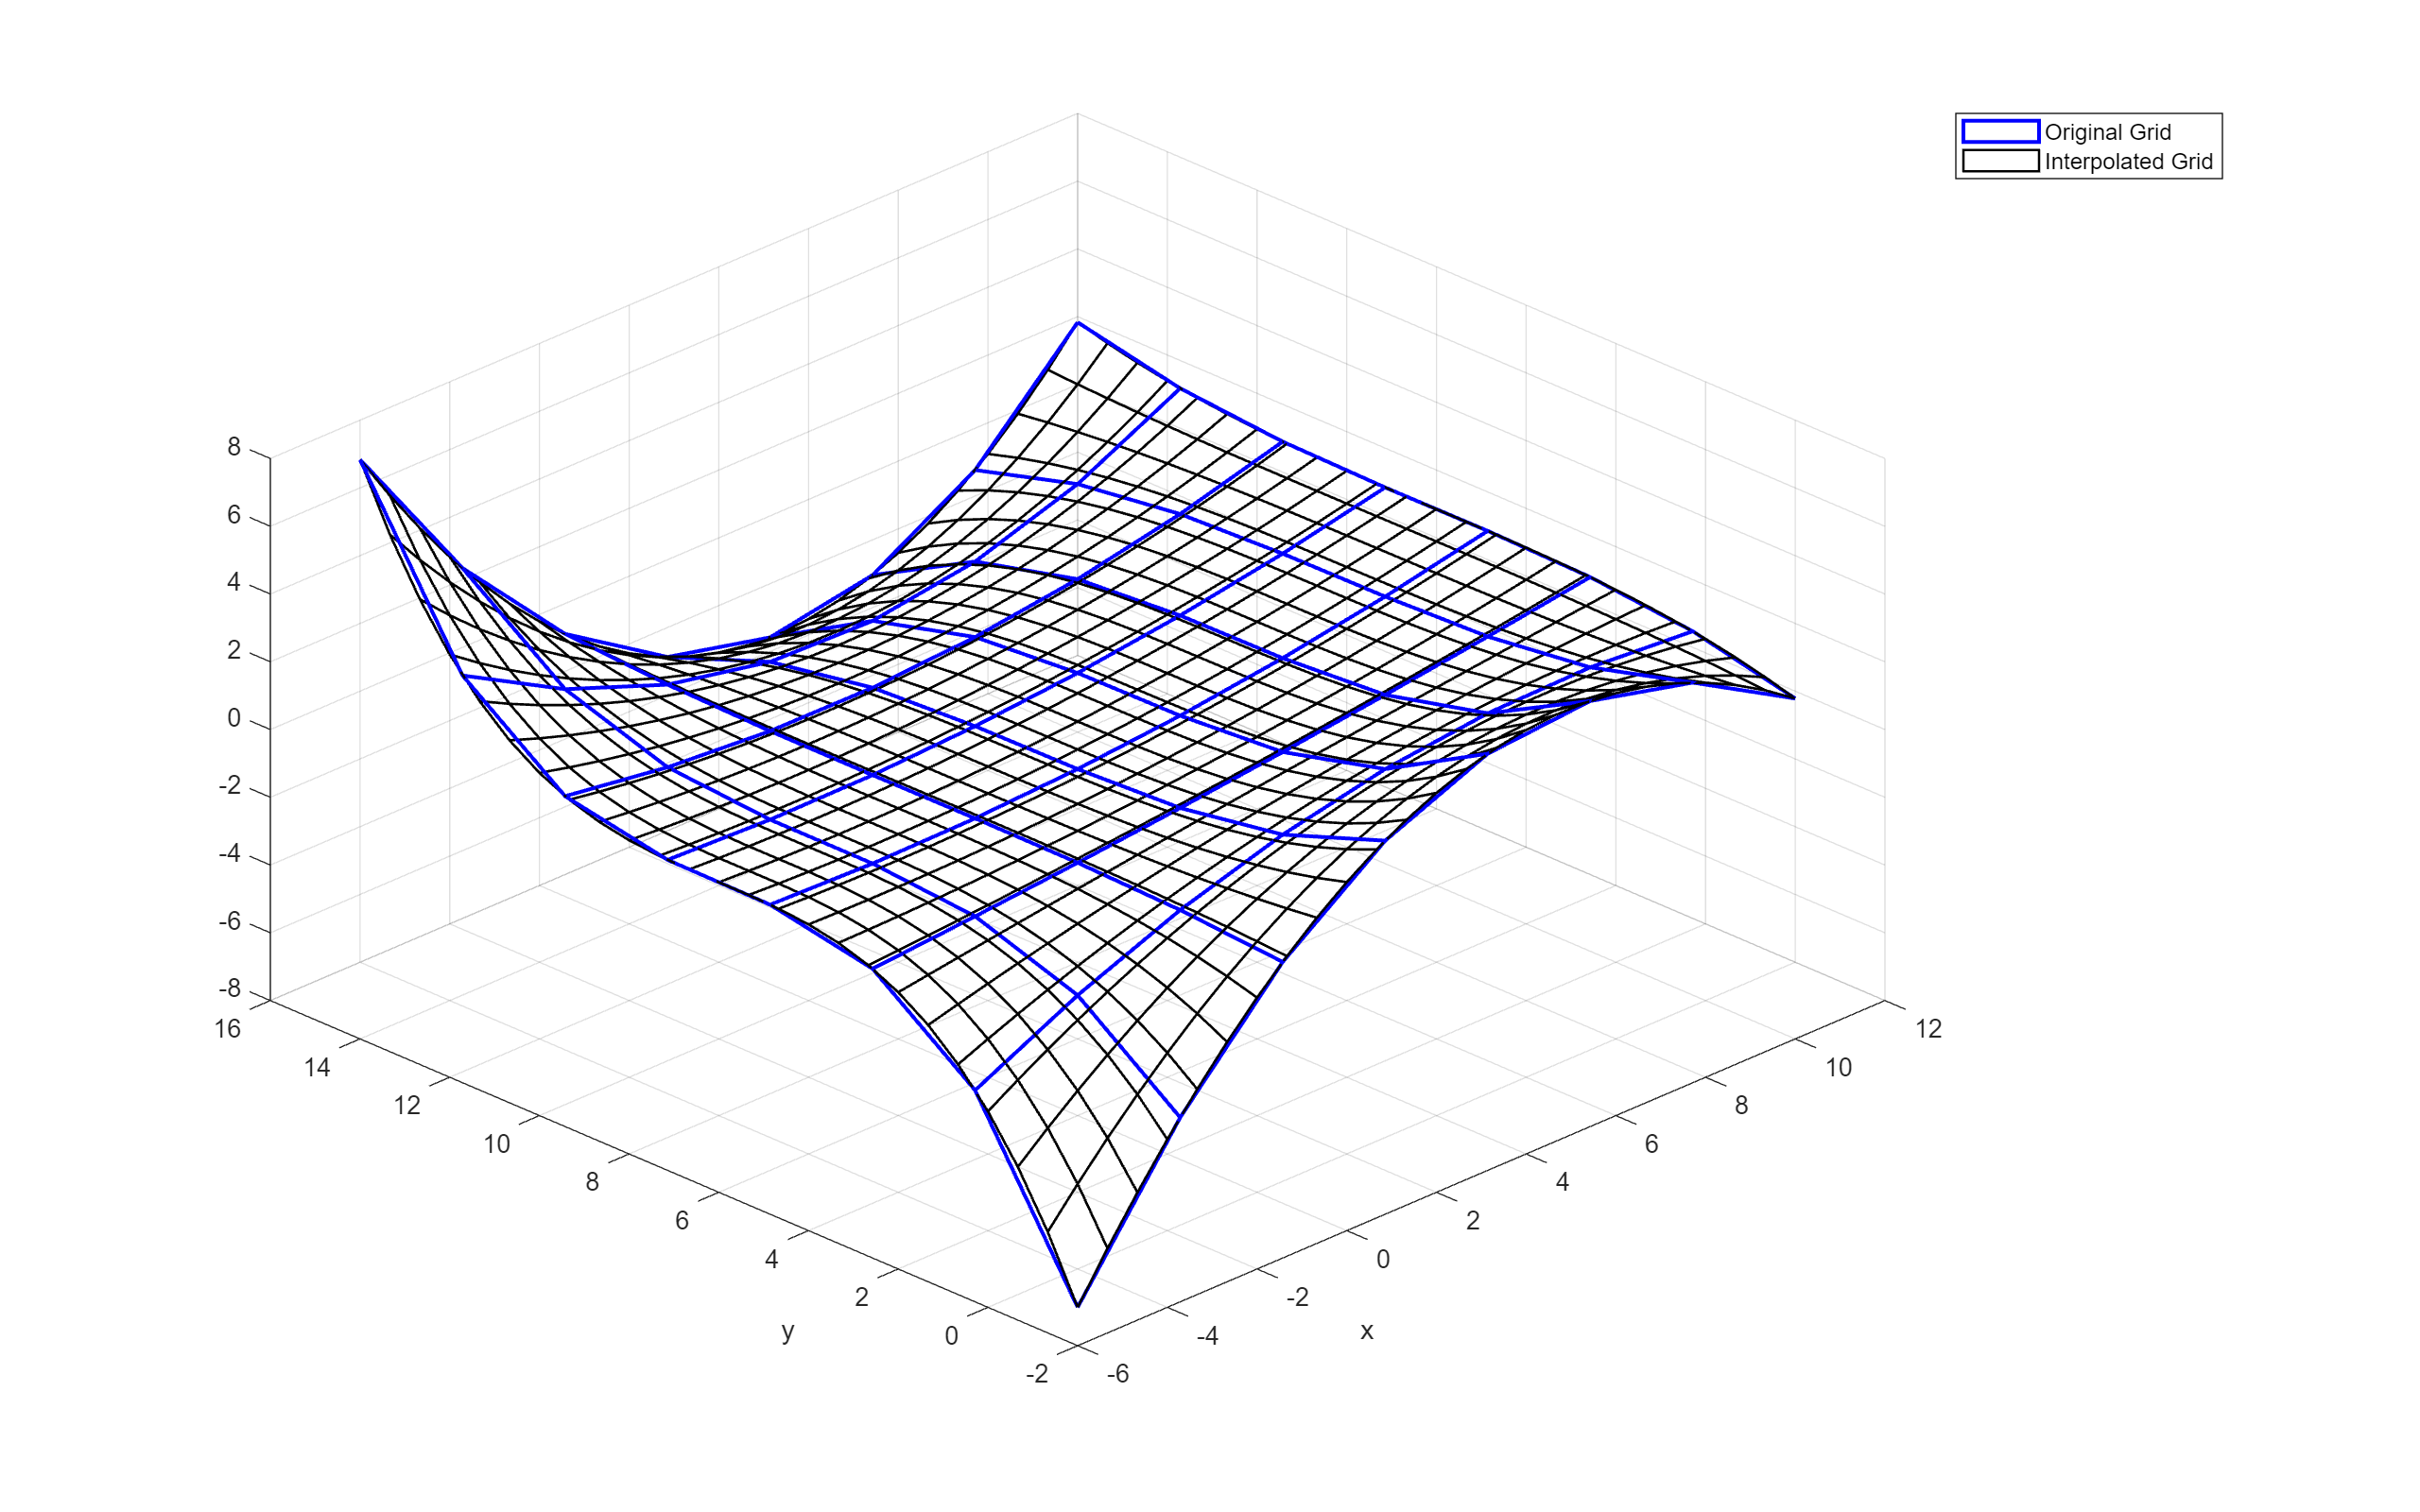

f = figure;
surf(xx0,yy0,zz0,'FaceColor','none','EdgeColor','b','LineWidth',1.5);hold on
surf(xx1,yy1,zz1,'FaceColor','none','LineWidth',1);hold on
view([-45 42]); xlabel('x'); ylabel('y'); 
legend('Original Grid','Interpolated Grid')
set(f,'Units','normalized','Position',[0,0,1,1])

# **PolyInterpScatterZ**

**Interpolation 3D Scatters**

x_interp = linspace(-5,0.3,100)';
y_interp = linspace(15,-1,100)';
z_scatter = PolyInterpScatterZ(x_interp,y_interp,mx_fit_pos);

Plot to Check

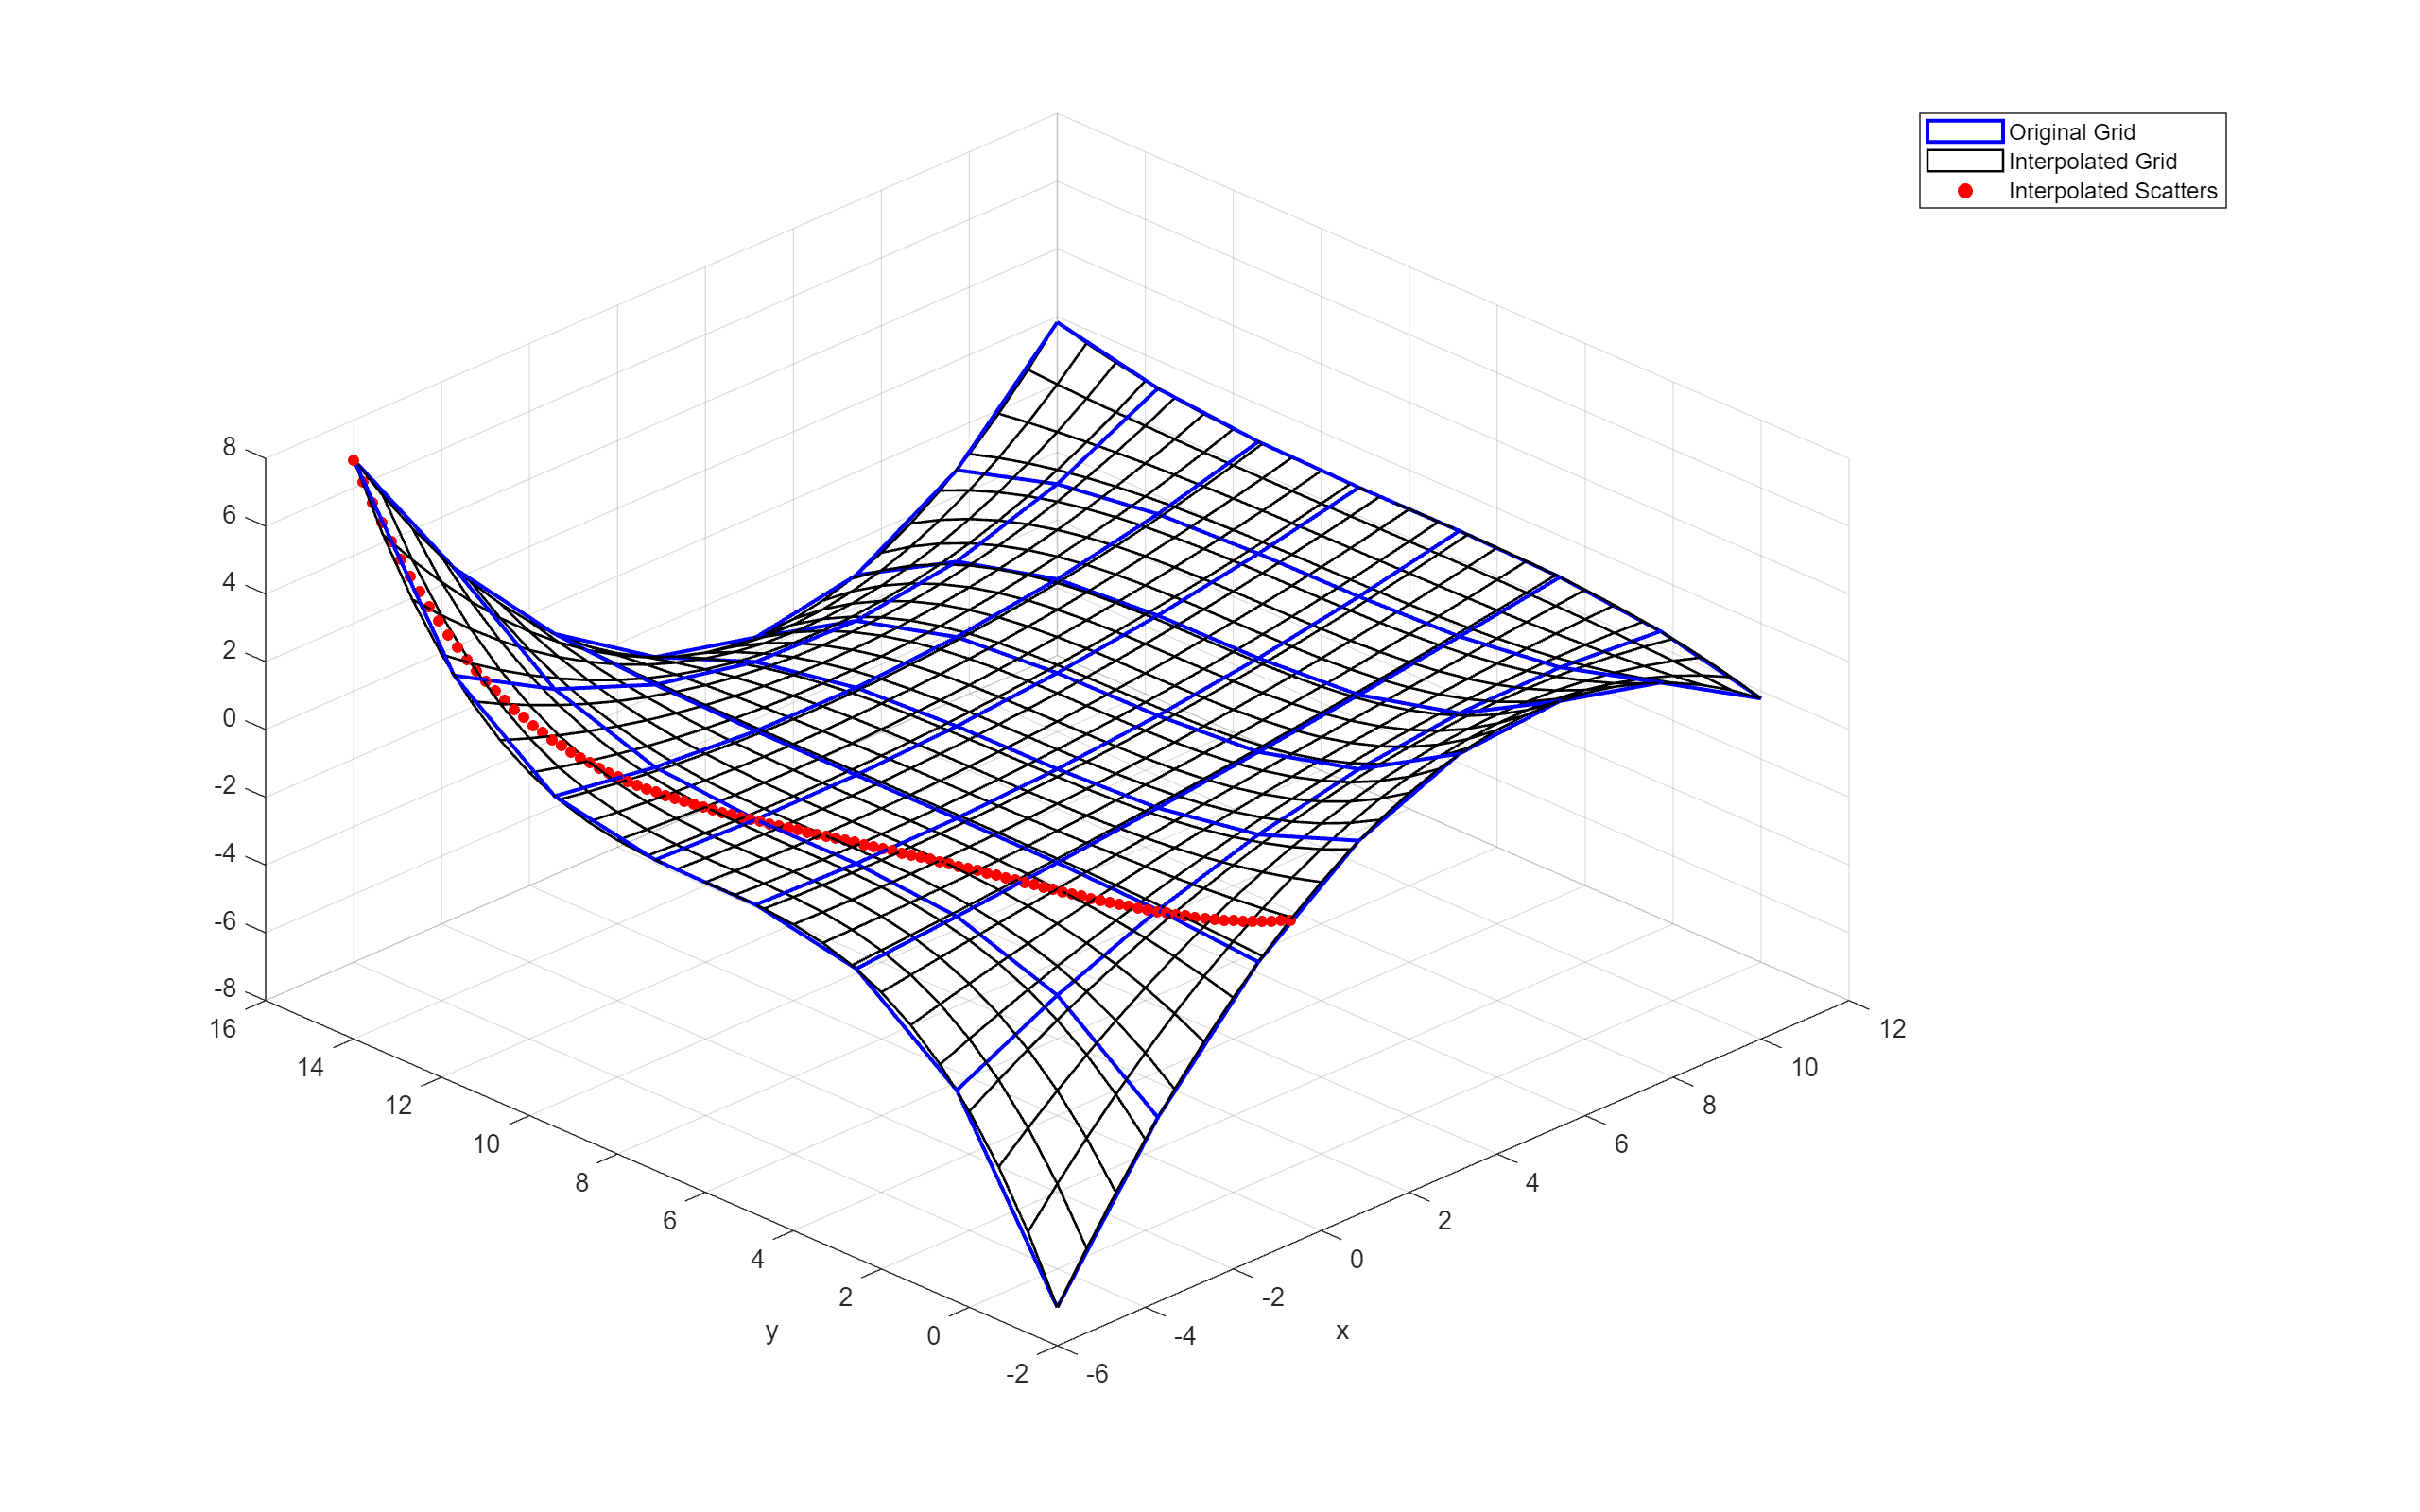

scatter3(x_interp,y_interp,z_scatter,20,'red','filled');hold on
legend('Original Grid','Interpolated Grid','Interpolated Scatters')

# **polyfit3**

**Fit the 4th Dimension Data using x,y,z value**

order_mag = [3,3,3];

c_fit_mag = polyfit3(xs0,ys0,zs0,ms0,order_mag);

Return n*1 fitting coefficient, use GetPolyBasis Function to get the fitting formular.

fc = GetPolyBasis(3,order_mag);
whos fc

  Name      Size            Bytes  Class              Attributes

  fc        1x1                32  function_handle              



# **PolyInterpScatterMag**

**Interpolation for the 4th Dimention**

[xs1,ys1,zs1] = ...
    deal(reshape(xx1,[],1),reshape(yy1,[],1),reshape(zz1,[],1));

ms1 = PolyInterpScatterMag(xs1,ys1,zs1,c_fit_mag,order_mag);

**Plot**

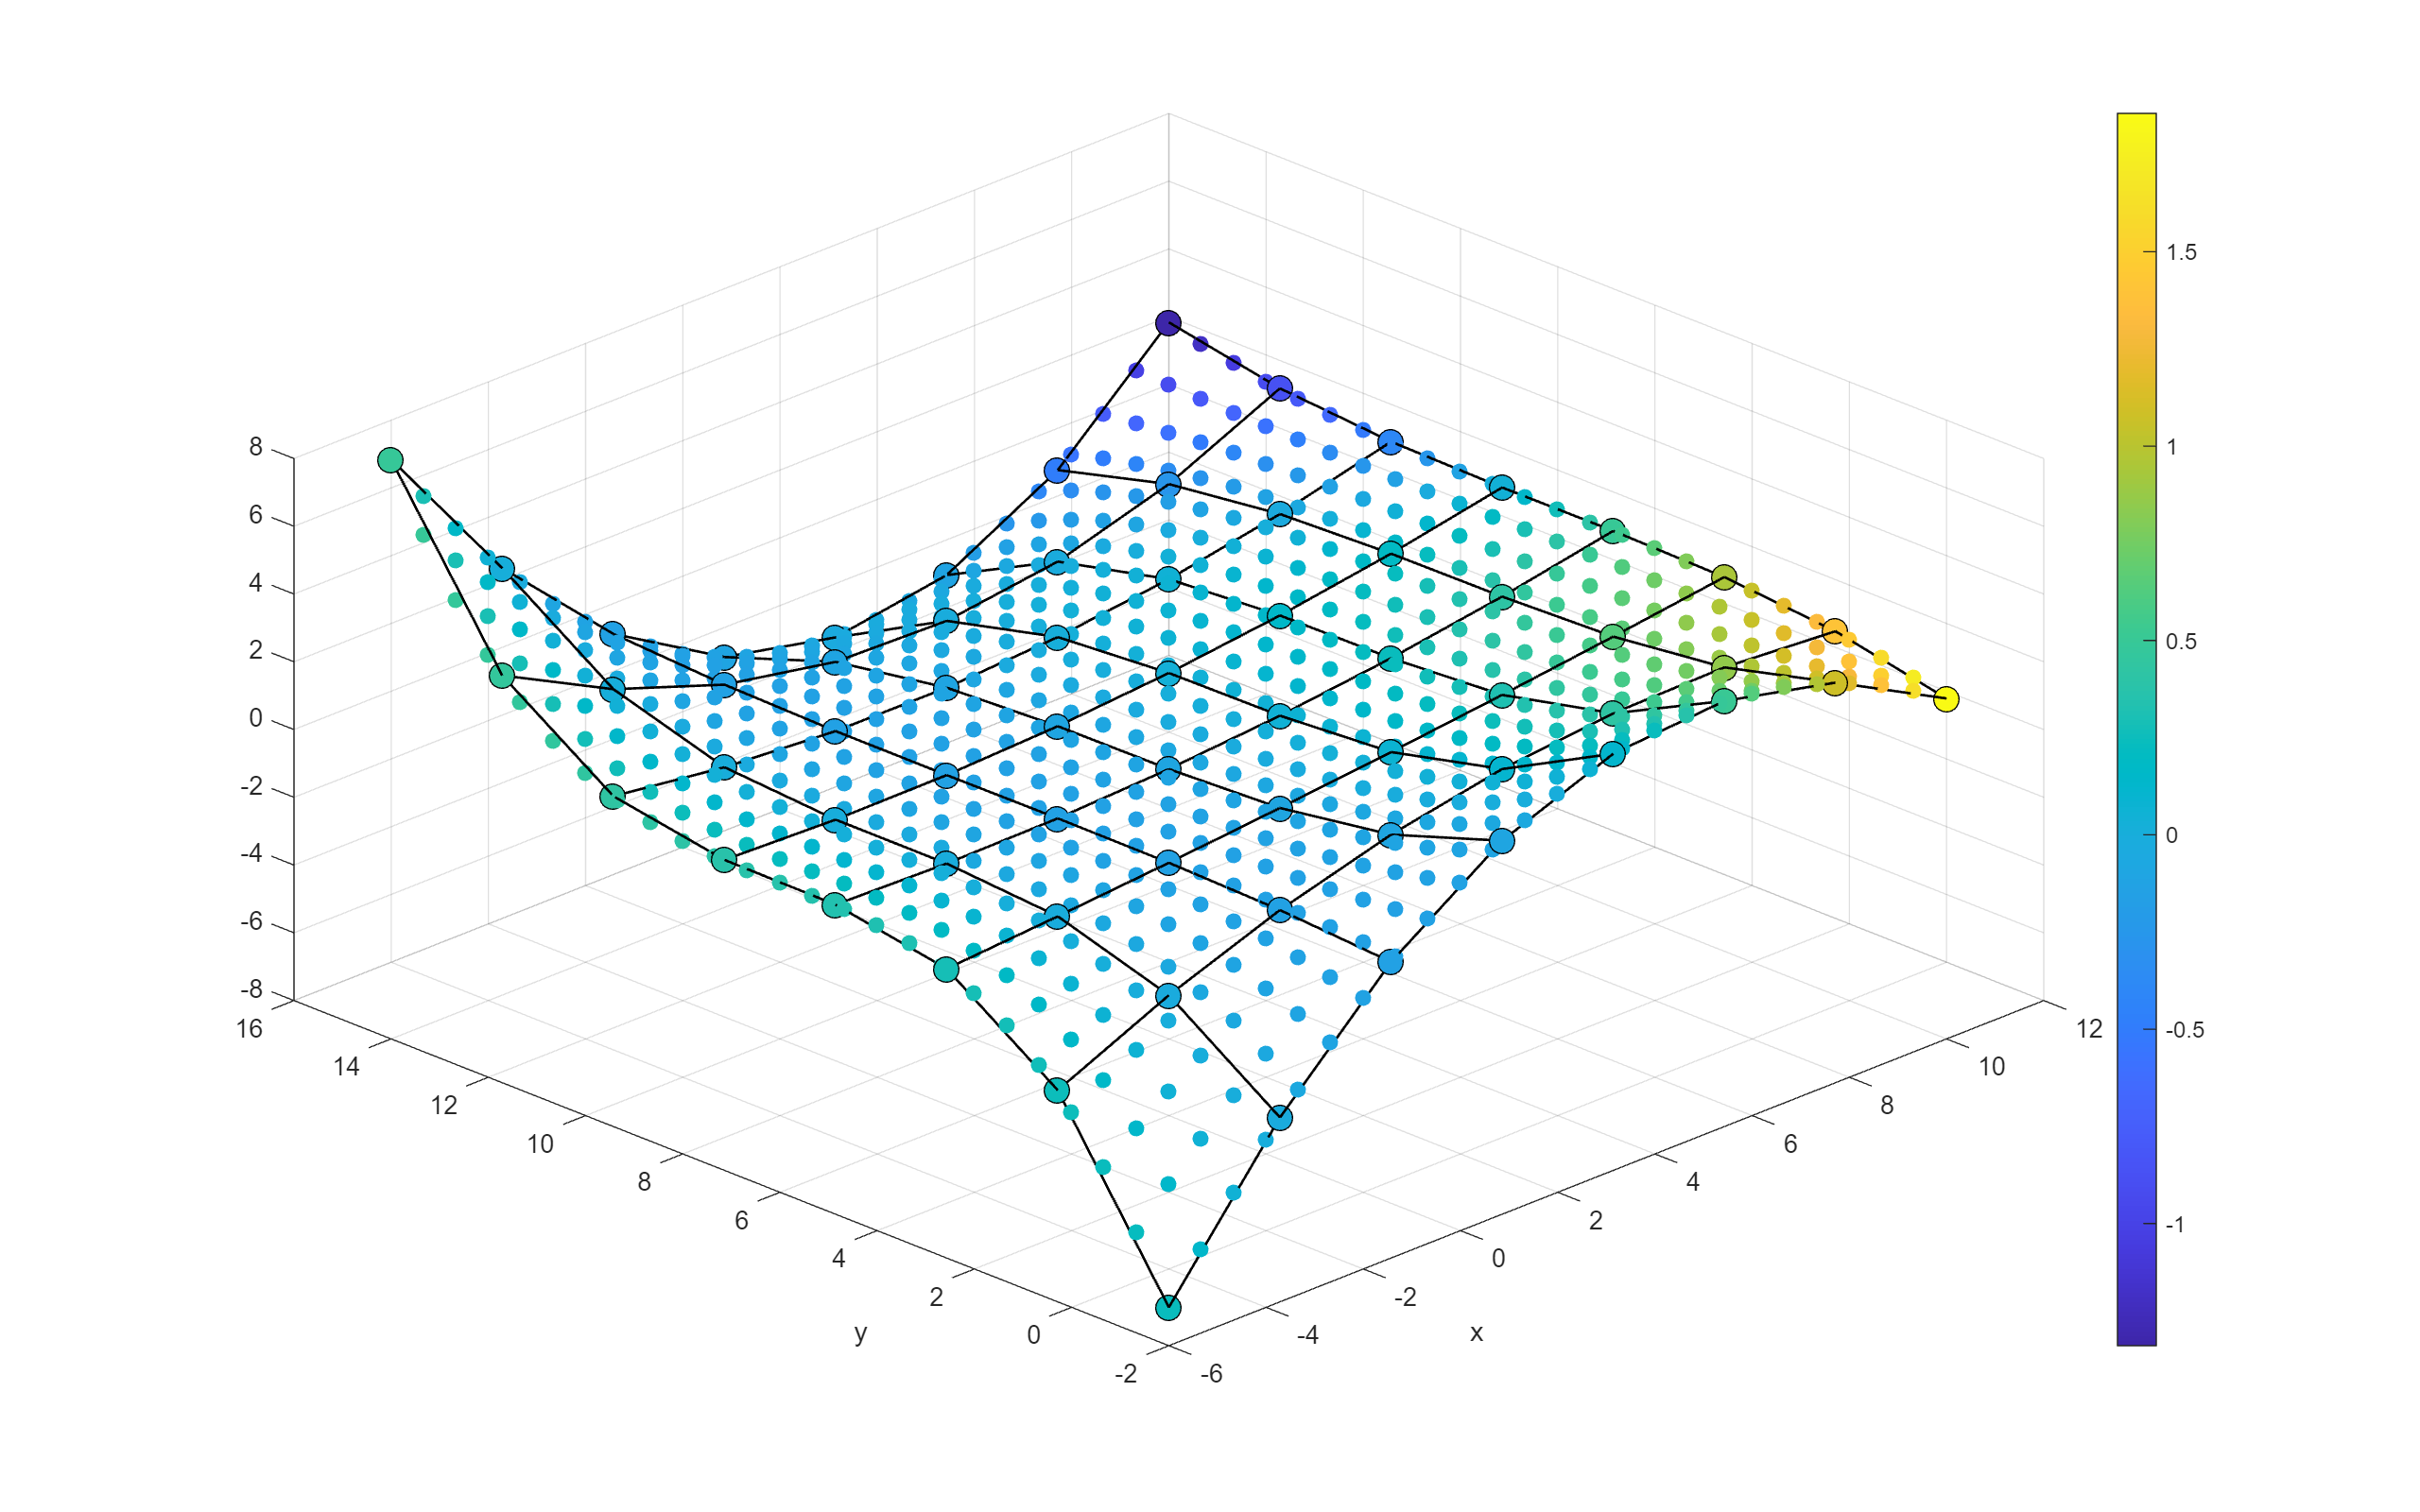

limc = [min([ms1;ms0]) max([ms1;ms0])];

f = figure;
surf(xx0,yy0,zz0,'FaceColor','none','LineWidth',1);hold on
scatter3(xs0,ys0,zs0,100,ms0,'filled','MarkerEdgeColor','k'); hold on
scatter3(xs1,ys1,zs1,40,ms1,'filled'); hold on
view([-45 42]); xlabel('x'); ylabel('y');clim(limc); colorbar
set(f,'Units','normalized','Position',[0,0,1,1])

# **Bezier Fitting and Interpolation**

**Similar to polynomials fitting and Interpolation, more stable on Higher Order**

**bezierfit2****:**

**BezierInterpSurf****:**

**BezierInterpScatterZ**

**bezierfit3**

**BezierInterpScatterMag**

# **Polynomials vs. Bezier**

**Compare using 10th Order Fitting **

x1 = linspace(-5,11,25)';
y1 = linspace(-1,15,25)';
order_pos = [10,10];

mx_fit_pos1 = polyfit2(xs0,ys0,zs0,order_pos,'matrix');
[xx1,yy1,zz1] = PolyInterpSurf(x1,y1,mx_fit_pos1);

[mx_fit_pos2,kb] = bezierfit2(xs0,ys0,zs0,order_pos,'matrix');
[xx2,yy2,zz2] = BezierInterpSurf(x1,y1,mx_fit_pos2,kb);

**Plot to Check**

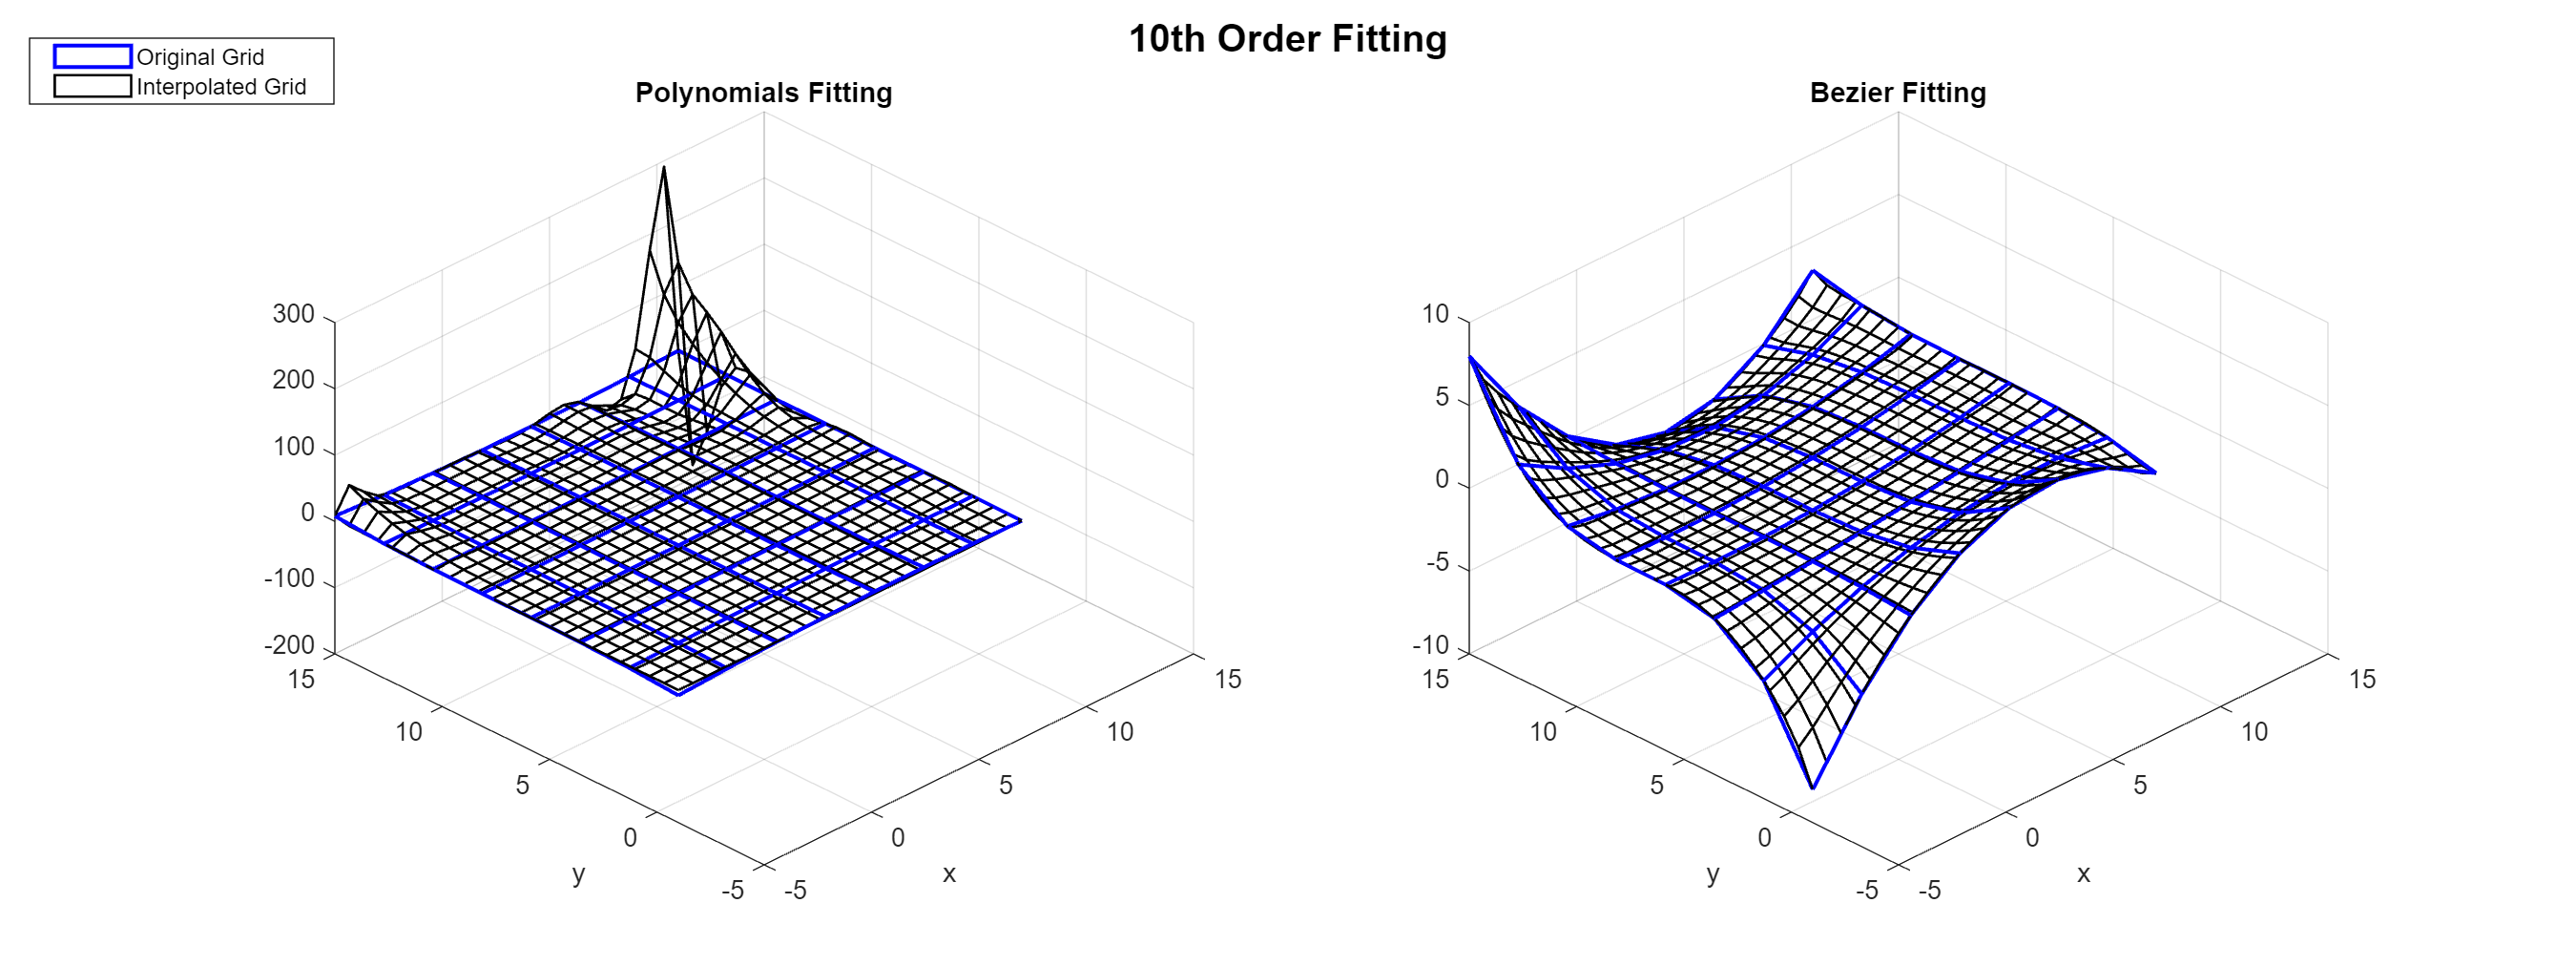

f = figure;
subplot(1,2,1)
surf(xx0,yy0,zz0,'FaceColor','none','EdgeColor','b','LineWidth',1.5);hold on
surf(xx1,yy1,zz1,'FaceColor','none','LineWidth',1);hold on
view([-45 42]); xlabel('x'); ylabel('y'); 
title('Polynomials Fitting')
subplot(1,2,2)
surf(xx0,yy0,zz0,'FaceColor','none','EdgeColor','b','LineWidth',1.5);hold on
surf(xx2,yy2,zz2,'FaceColor','none','LineWidth',1);hold on
view([-45 42]); xlabel('x'); ylabel('y');
title('Bezier Fitting')
legend('Original Grid','Interpolated Grid',"Position", [0.018563,0.89727,0.10391,0.058081])
sgtitle('10th Order Fitting','fontweight','bold')
set(f,'Units','normalized','Position',[0,0,1,0.6])

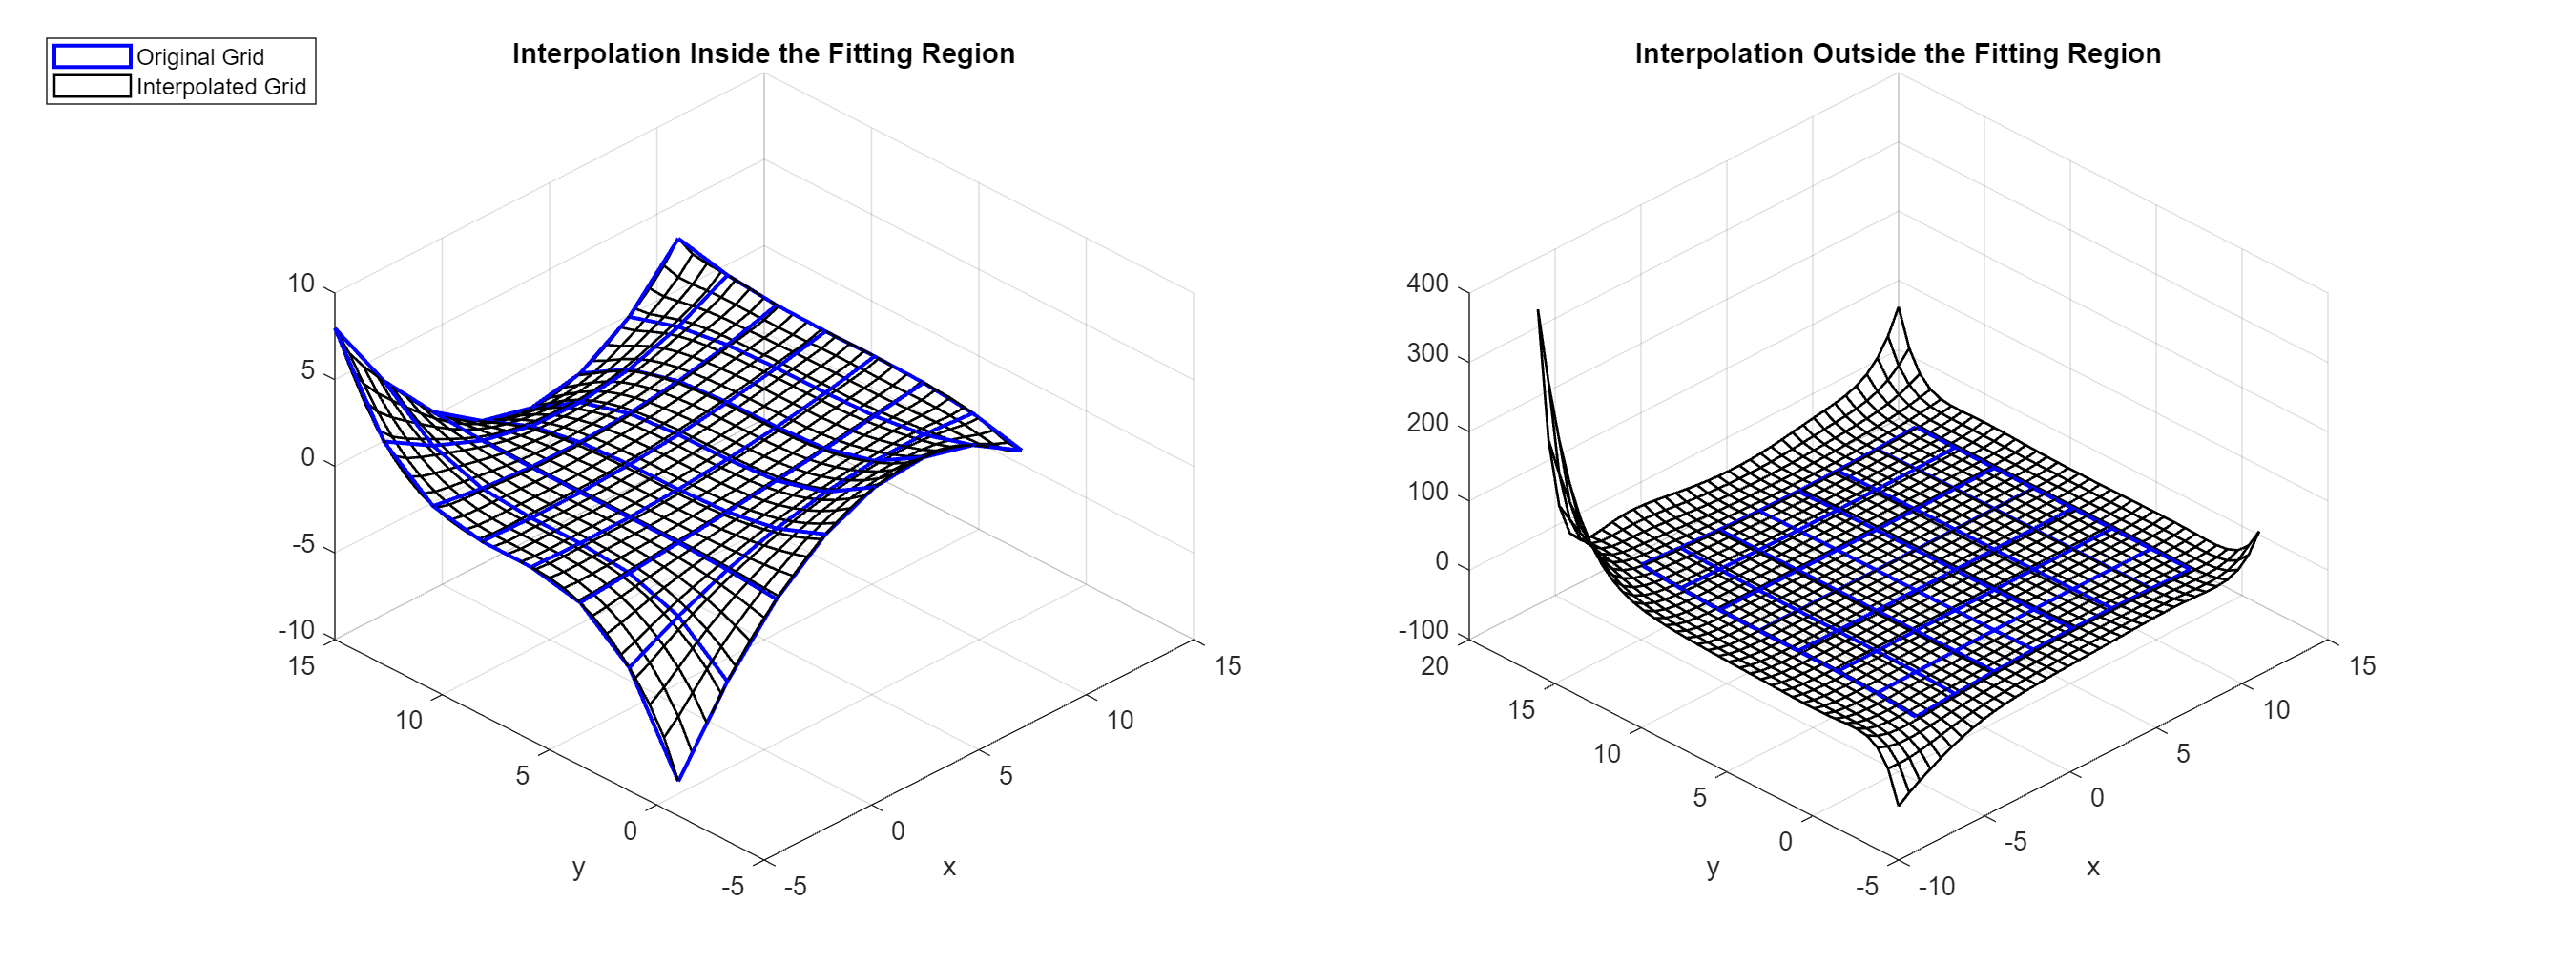

f = figure;
subplot(1,2,1)
surf(xx0,yy0,zz0,'FaceColor','none','EdgeColor','b','LineWidth',1.5);hold on
surf(xx2,yy2,zz2,'FaceColor','none','LineWidth',1);hold on
view([-45 42]); xlabel('x'); ylabel('y');
title('Interpolation Inside the Fitting Region')

x1 = linspace(-8,13,35)';
y1 = linspace(-3,18,35)';
order_pos = [10,10];

[mx_fit_pos3,kb3] = bezierfit2(xs0,ys0,zs0,order_pos,'matrix');
[xx3,yy3,zz3] = BezierInterpSurf(x1,y1,mx_fit_pos3,kb3);

subplot(1,2,2)
surf(xx0,yy0,zz0,'FaceColor','none','EdgeColor','b','LineWidth',1.5);hold on
surf(xx3,yy3,zz3,'FaceColor','none','LineWidth',1);hold on
view([-45 42]); xlabel('x'); ylabel('y');
title('Interpolation Outside the Fitting Region')
legend('Original Grid','Interpolated Grid',"Position", [0.018563,0.89727,0.10391,0.058081])
set(f,'Units','normalized','Position',[0,0,1,0.6])

function [xx0,yy0,zz0,mm0] = newdata(steps)
x0 = linspace(-5,11,steps)';
y0 = linspace(-1,15,steps)';

[xx0,yy0] = meshgrid(x0,y0);
zz0 = -(xx0.*10+1-xx0.^2).*(yy0.*147-yy0.^2.*21+1+yy0.^3-368)/80+xx0.^2-yy0.^2/30;
zz0 = zz0/max(abs(zz0),[],'all')*8;
mm0 = -zz0.^3-3*yy0.*xx0.^3+0.2*yy0.^2+300*xx0.^2; 
mm0 = mm0/max(abs(mm0),[],'all')*2;
mm0 = mm0-median(mm0,"all");
end